**EJERCICIO 1**

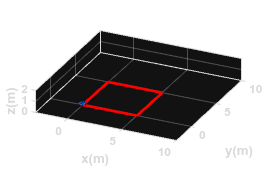


clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 8;
ts = 0.1;
t = 0:ts:tf;
N = length(t);

% Parametros del robot
r = 0.05;
l = 0.2;

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1 = zeros(1,N+1);
y1 = zeros(1,N+1);
phi = zeros(1,N+1);
x1(1) = 0;
y1(1) = 0;
phi(1) = pi/2;

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%
hx = zeros(1,N+1);
hy = zeros(1,N+1);
hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
u = [5*ones(1,10) 0*ones(1,10) 5*ones(1,10) 0*ones(1,10) 5*ones(1,10) 0*ones(1,10) 5*ones(1,10) 0*ones(1,11)];
w = [0*ones(1,10) -pi/2*ones(1,10) 0*ones(1,10) -pi/2*ones(1,10) 0*ones(1,10) -pi/2*ones(1,10) 0*ones(1,10) -pi/2*ones(1,11)];

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
xp1 = zeros(1,N);
yp1 = zeros(1,N);
wr = zeros(1,N);
wl = zeros(1,N);

for k=1:N
    phi(k+1) = phi(k) + w(k)*ts;
    xp1(k) = u(k)*cos(phi(k+1));
    yp1(k) = u(k)*sin(phi(k+1));
    wr(k) = (2*u(k) + l*w(k))/(2*r);
    wl(k) = (2*u(k) - l*w(k))/(2*r);
    x1(k+1) = x1(k) + xp1(k)*ts;
    y1(k+1) = y1(k) + yp1(k)*ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%
scene=figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen=get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([25 25]);
axis([-3 10 -3 10 0 2]);
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
step=1;
for k=1:step:N
    delete(H1);
    delete(H2);
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    pause(ts);
end

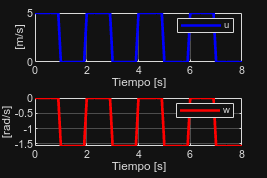


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;
set(graph,'position',sizeScreen);
subplot(211)
plot(t,u,'b','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m/s]'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

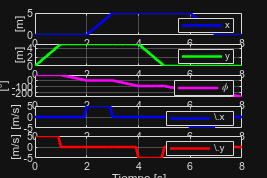


graph2=figure;
set(graph2,'position',sizeScreen);
subplot(511)
plot(t,x1(1:N),'b','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m]'),legend('x');
subplot(512)
plot(t,y1(1:N),'g','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m]'),legend('y');
subplot(513)
plot(t,rad2deg(phi(1:N)),'m','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[°]'),legend('\phi');
subplot(514)
plot(t,xp1,'b','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m/s]'),legend('\.{x}');
subplot(515)
plot(t,yp1,'r','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m/s]'),legend('\.{y}');

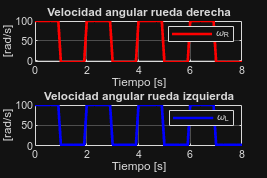


graph3=figure;
set(graph3,'position',sizeScreen);
subplot(211)
plot(t,wr,'r','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[rad/s]'),title('Velocidad angular rueda derecha'),legend('\omega_R');
subplot(212)
plot(t,wl,'b','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[rad/s]'),title('Velocidad angular rueda izquierda'),legend('\omega_L');

**EJERCICIO 2**

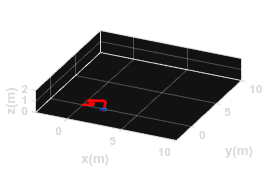

clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 8;
ts = 0.1;
t = 0:ts:tf;
N = length(t);

% Parametros del robot
r = 0.05;
l = 0.2;

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1 = zeros(1,N+1);
y1 = zeros(1,N+1);
phi = zeros(1,N+1);
x1(1) = 0;
y1(1) = 0;
phi(1) = 0;

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%
hx = zeros(1,N+1);
hy = zeros(1,N+1);
hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
u = [0*ones(1,10) 1*ones(1,10) 0*ones(1,10) 1*ones(1,10) 0*ones(1,10) 1.5*ones(1,10) 0*ones(1,10) 2.2*ones(1,11)];
w = [pi/6*ones(1,10) 0*ones(1,10) 2*pi/3*ones(1,10) 0*ones(1,10) -13*pi/18*ones(1,10) 0*ones(1,10) -pi/2*ones(1,10) 0*ones(1,11)];

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
xp1 = zeros(1,N);
yp1 = zeros(1,N);
wr = zeros(1,N);
wl = zeros(1,N);

for k=1:N
    phi(k+1) = phi(k) + w(k)*ts;
    xp1(k) = u(k)*cos(phi(k+1));
    yp1(k) = u(k)*sin(phi(k+1));
    wr(k) = (2*u(k) + l*w(k))/(2*r);
    wl(k) = (2*u(k) - l*w(k))/(2*r);
    x1(k+1) = x1(k) + xp1(k)*ts;
    y1(k+1) = y1(k) + yp1(k)*ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%
scene=figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen=get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([25 25]);
axis([-3 10 -3 10 0 2]);
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
step=1;
for k=1:step:N
    delete(H1);
    delete(H2);
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    pause(ts);
end

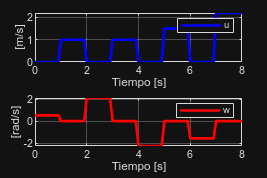


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;
set(graph,'position',sizeScreen);
subplot(211)
plot(t,u,'b','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m/s]'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

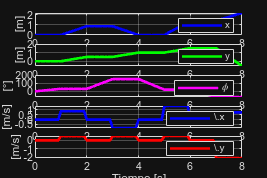


graph2=figure;
set(graph2,'position',sizeScreen);
subplot(511)
plot(t,x1(1:N),'b','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m]'),legend('x');
subplot(512)
plot(t,y1(1:N),'g','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m]'),legend('y');
subplot(513)
plot(t,rad2deg(phi(1:N)),'m','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[°]'),legend('\phi');
subplot(514)
plot(t,xp1,'b','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m/s]'),legend('\.{x}');
subplot(515)
plot(t,yp1,'r','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m/s]'),legend('\.{y}');

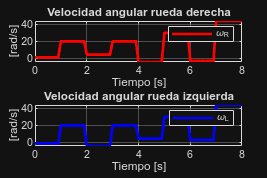


graph3=figure;
set(graph3,'position',sizeScreen);
subplot(211)
plot(t,wr,'r','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[rad/s]'),title('Velocidad angular rueda derecha'),legend('\omega_R');
subplot(212)
plot(t,wl,'b','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[rad/s]'),title('Velocidad angular rueda izquierda'),legend('\omega_L');

**EJERCICIO 3**

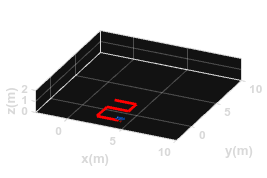

clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 8.9;
ts = 0.1;
t = 0:ts:tf;
N = length(t);

% Parametros del robot
r = 0.05;
l = 0.2;

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1 = zeros(1,N+1);
y1 = zeros(1,N+1);
phi = zeros(1,N+1);
x1(1) = 2;
y1(1) = 2;
phi(1) = 0;

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%
hx = zeros(1,N+1);
hy = zeros(1,N+1);
hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
u = [2*ones(1,10) 0*ones(1,10) 1.5*ones(1,10) 0*ones(1,10) 2*ones(1,10) 0*ones(1,10) 2*ones(1,10) 0*ones(1,10) 2.5*ones(1,10)];
w = [0*ones(1,10) -pi/2*ones(1,10) 0*ones(1,10) -pi/2*ones(1,10) 0*ones(1,10) pi/2*ones(1,10) 0*ones(1,10) pi/2*ones(1,10) 0*ones(1,10)];

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
xp1 = zeros(1,N);
yp1 = zeros(1,N);
wr = zeros(1,N);
wl = zeros(1,N);

for k=1:N
    phi(k+1) = phi(k) + w(k)*ts;
    xp1(k) = u(k)*cos(phi(k+1));
    yp1(k) = u(k)*sin(phi(k+1));
    wr(k) = (2*u(k) + l*w(k))/(2*r);
    wl(k) = (2*u(k) - l*w(k))/(2*r);
    x1(k+1) = x1(k) + xp1(k)*ts;
    y1(k+1) = y1(k) + yp1(k)*ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%
scene=figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen=get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([25 25]);
axis([-3 10 -3 10 0 2]);
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
step=1;
for k=1:step:N
    delete(H1);
    delete(H2);
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    pause(ts);
end

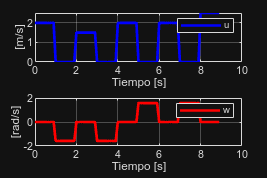


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;
set(graph,'position',sizeScreen);
subplot(211)
plot(t,u,'b','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m/s]'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

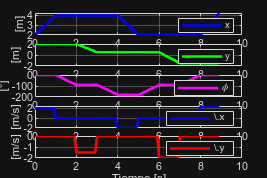


graph2=figure;
set(graph2,'position',sizeScreen);
subplot(511)
plot(t,x1(1:N),'b','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m]'),legend('x');
subplot(512)
plot(t,y1(1:N),'g','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m]'),legend('y');
subplot(513)
plot(t,rad2deg(phi(1:N)),'m','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[°]'),legend('\phi');
subplot(514)
plot(t,xp1,'b','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m/s]'),legend('\.{x}');
subplot(515)
plot(t,yp1,'r','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[m/s]'),legend('\.{y}');

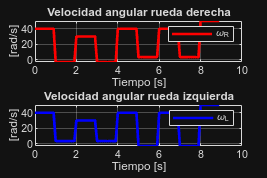


graph3=figure;
set(graph3,'position',sizeScreen);
subplot(211)
plot(t,wr,'r','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[rad/s]'),title('Velocidad angular rueda derecha'),legend('\omega_R');
subplot(212)
plot(t,wl,'b','LineWidth',2),grid on,xlabel('Tiempo [s]'),ylabel('[rad/s]'),title('Velocidad angular rueda izquierda'),legend('\omega_L');